**Question 1**

t = [10 15 20 25 40 50 55 60 75]

t =     10    15    20    25    40    50    55    60    75


t = t'

t =     10
    15
    20
    25
    40
    50
    55
    60
    75


TS = [5 20 18 40 33 54 70 60 78]

TS =      5    20    18    40    33    54    70    60    78


TS = TS'

TS =      5
    20
    18
    40
    33
    54
    70
    60
    78


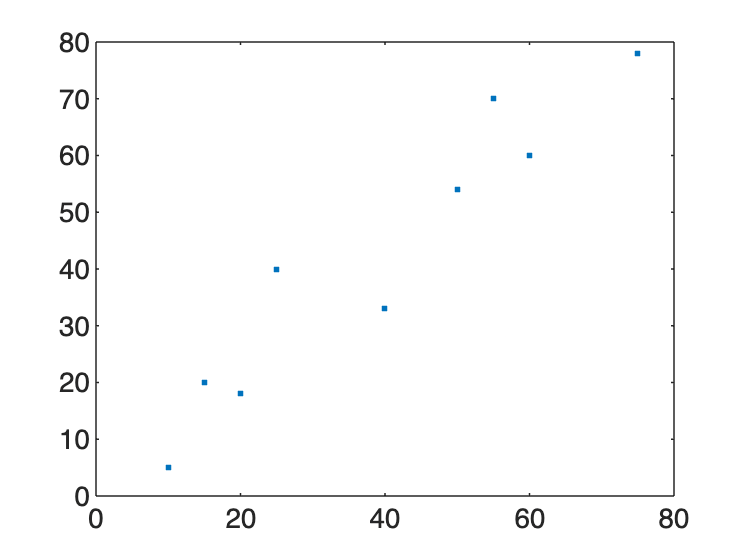


plot(t, TS, ".")


% TS = a1 + b1T
a1 = ones(1, length(TS))

a1 =      1     1     1     1     1     1     1     1     1


a1 = a1'

a1 =      1
     1
     1
     1
     1
     1
     1
     1
     1


a2 = TS

a2 =      5
    20
    18
    40
    33
    54
    70
    60
    78


A1 = horzcat(a1, a2)

A1 =      1     5
     1    20
     1    18
     1    40
     1    33
     1    54
     1    70
     1    60
     1    78



Astar = A1'*A1

Astar =            9         378
         378       20938


ystar = A1'*TS

ystar =          378
       20938



c1 = Astar\ystar

c1 =      0
     1




% TS = a2 + b2T^2
a1 = ones(1, length(TS))

a1 =      1     1     1     1     1     1     1     1     1


a1 = a1'

a1 =      1
     1
     1
     1
     1
     1
     1
     1
     1


a2 = TS

a2 =      5
    20
    18
    40
    33
    54
    70
    60
    78


a3 = TS.^2

a3 =           25
         400
         324
        1600
        1089
        2916
        4900
        3600
        6084


A2 = horzcat(a1, a2, a3)

A2 =            1           5          25
           1          20         400
           1          18         324
           1          40        1600
           1          33        1089
           1          54        2916
           1          70        4900
           1          60        3600
           1          78        6084



Astar = A2'*A2

Astar =            9         378       20938
         378       20938     1304910
       20938     1304910    86499634


ystar = A2'*TS

ystar =          378
       20938
     1304910



c2 = Astar\ystar

c2 =      0
     1
     0



t = [10 15 20 25 40 50 55 60 75]

t =     10    15    20    25    40    50    55    60    75


TS = [5 20 18 40 33 54 70 60 78]

TS =      5    20    18    40    33    54    70    60    78



% TS = a3 + b3T^(1/2)
a1 = ones(1, length(TS))

a1 =      1     1     1     1     1     1     1     1     1


a1 = a1'

a1 =      1
     1
     1
     1
     1
     1
     1
     1
     1


a2 = TS

a2 =      5    20    18    40    33    54    70    60    78


a2 = a2'

a2 =      5
    20
    18
    40
    33
    54
    70
    60
    78


a3 = sqrt(TS)

a3 =     2.2361    4.4721    4.2426    6.3246    5.7446    7.3485    8.3666    7.7460    8.8318


a3 = a3'

a3 =     2.2361
    4.4721
    4.2426
    6.3246
    5.7446
    7.3485
    8.3666
    7.7460
    8.8318


A3 = horzcat(a1, a2, a3)

A3 =     1.0000    5.0000    2.2361
    1.0000   20.0000    4.4721
    1.0000   18.0000    4.2426
    1.0000   40.0000    6.3246
    1.0000   33.0000    5.7446
    1.0000   54.0000    7.3485
    1.0000   70.0000    8.3666
    1.0000   60.0000    7.7460
    1.0000   78.0000    8.8318



Astar = A3'*A3

Astar = 1.0e+04 *

    0.0009    0.0378    0.0055
    0.0378    2.0938    0.2756
    0.0055    0.2756    0.0378


ystar = A3'*TS'

ystar = 1.0e+04 *

    0.0378
    2.0938
    0.2756



c3 = Astar\ystar

c3 =      0
     1
     0



ts = 10:0.1:75

ts =    10.0000   10.1000   10.2000   10.3000   10.4000   10.5000   10.6000   10.7000   10.8000   10.9000   11.0000   11.1000   11.2000   11.3000   11.4000   11.5000   11.6000   11.7000   11.8000   11.9000   12.0000   12.1000   12.2000   12.3000   12.4000   12.5000   12.6000   12.7000   12.8000   12.9000   13.0000   13.1000   13.2000   13.3000   13.4000   13.5000   13.6000   13.7000   13.8000   13.9000   14.0000   14.1000   14.2000   14.3000   14.4000   14.5000   14.6000   14.7000   14.8000   14.9000


y1 = c1(1) + ts * c1(2)

y1 =    10.0000   10.1000   10.2000   10.3000   10.4000   10.5000   10.6000   10.7000   10.8000   10.9000   11.0000   11.1000   11.2000   11.3000   11.4000   11.5000   11.6000   11.7000   11.8000   11.9000   12.0000   12.1000   12.2000   12.3000   12.4000   12.5000   12.6000   12.7000   12.8000   12.9000   13.0000   13.1000   13.2000   13.3000   13.4000   13.5000   13.6000   13.7000   13.8000   13.9000   14.0000   14.1000   14.2000   14.3000   14.4000   14.5000   14.6000   14.7000   14.8000   14.9000


y2 = c2(1) + ts * c2(2) + ts.^2 * c2(3)

y2 =    10.0000   10.1000   10.2000   10.3000   10.4000   10.5000   10.6000   10.7000   10.8000   10.9000   11.0000   11.1000   11.2000   11.3000   11.4000   11.5000   11.6000   11.7000   11.8000   11.9000   12.0000   12.1000   12.2000   12.3000   12.4000   12.5000   12.6000   12.7000   12.8000   12.9000   13.0000   13.1000   13.2000   13.3000   13.4000   13.5000   13.6000   13.7000   13.8000   13.9000   14.0000   14.1000   14.2000   14.3000   14.4000   14.5000   14.6000   14.7000   14.8000   14.9000


y3 = c3(1) + ts * c3(2) + ts.^2 * c3(3)

y3 =    10.0000   10.1000   10.2000   10.3000   10.4000   10.5000   10.6000   10.7000   10.8000   10.9000   11.0000   11.1000   11.2000   11.3000   11.4000   11.5000   11.6000   11.7000   11.8000   11.9000   12.0000   12.1000   12.2000   12.3000   12.4000   12.5000   12.6000   12.7000   12.8000   12.9000   13.0000   13.1000   13.2000   13.3000   13.4000   13.5000   13.6000   13.7000   13.8000   13.9000   14.0000   14.1000   14.2000   14.3000   14.4000   14.5000   14.6000   14.7000   14.8000   14.9000


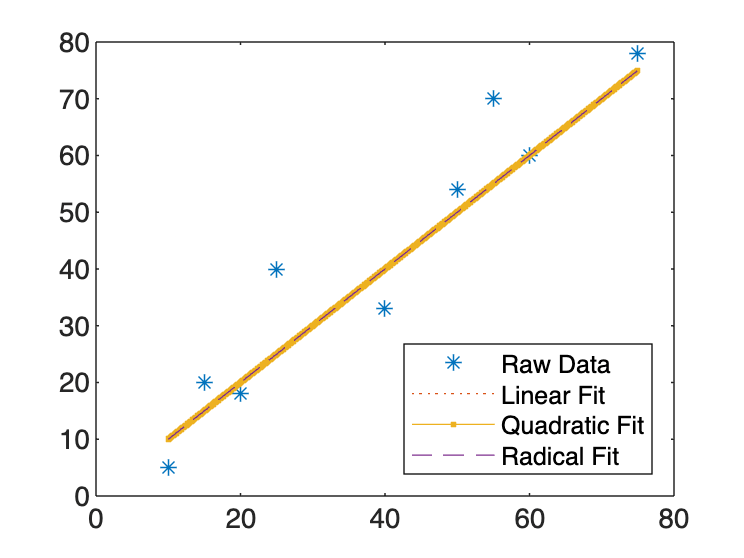


plot(t, TS, "*")
hold on
plot(ts, y1, ":")
plot(ts, y2, ".-")
plot(ts, y3, "--")
hold off
legend("Raw Data", "Linear Fit", "Quadratic Fit", "Radical Fit", "Location", "southeast")


% squared magnitude of error
e1 = TS - A1*c1

e1 =      0    15    13    35    28    49    65    55    73
   -15     0    -2    20    13    34    50    40    58
   -13     2     0    22    15    36    52    42    60
   -35   -20   -22     0    -7    14    30    20    38
   -28   -13   -15     7     0    21    37    27    45
   -49   -34   -36   -14   -21     0    16     6    24
   -65   -50   -52   -30   -37   -16     0   -10     8
   -55   -40   -42   -20   -27    -6    10     0    18
   -73   -58   -60   -38   -45   -24    -8   -18     0


e2 = TS - A2*c2

e2 =      0    15    13    35    28    49    65    55    73
   -15     0    -2    20    13    34    50    40    58
   -13     2     0    22    15    36    52    42    60
   -35   -20   -22     0    -7    14    30    20    38
   -28   -13   -15     7     0    21    37    27    45
   -49   -34   -36   -14   -21     0    16     6    24
   -65   -50   -52   -30   -37   -16     0   -10     8
   -55   -40   -42   -20   -27    -6    10     0    18
   -73   -58   -60   -38   -45   -24    -8   -18     0


e3 = TS - A3*c3

e3 =      0    15    13    35    28    49    65    55    73
   -15     0    -2    20    13    34    50    40    58
   -13     2     0    22    15    36    52    42    60
   -35   -20   -22     0    -7    14    30    20    38
   -28   -13   -15     7     0    21    37    27    45
   -49   -34   -36   -14   -21     0    16     6    24
   -65   -50   -52   -30   -37   -16     0   -10     8
   -55   -40   -42   -20   -27    -6    10     0    18
   -73   -58   -60   -38   -45   -24    -8   -18     0



me1 = norm(e1)

me1 = 213.4432

me2 = norm(e2)

me2 = 213.4432

me3 = norm(e3)

me3 = 213.4432

Idk wtf is wrong

**Q2**

a = 0

a = 0

b = 2

b = 2


% left endpoint
%N = 10
%dx = (b-a)/N
%x = a:dx:b-dx
%f = 4 .* x.^5 + 3 .* x.^3 -2
fL = zeros(100-10+1, 1)

fL =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i = 10:100
    N = i;
    dx = (b-a)/N;
    x = a:dx:b-dx;
    f = 4 .* x.^5 + 3 .* x.^3 -2;
    fL(i-9) = sum(f.*dx);
end
fL

fL =    36.6512
   37.8277
   38.8230
   39.6758
   40.4144
   41.0603
   41.6299
   42.1358
   42.5883
   42.9952



% trapezoidal
fT = zeros(100-10+1, 1)

fT =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i = 10:100
    N = i;
    dx = (b-a)/N;
    xl = a:dx:b-dx;
    xr = a+dx:dx:b;
    fl = 4 .* xl.^5 + 3 .* xl.^3 -2;
    fr = 4 .* xr.^5 + 3 .* xr.^3 -2;
    f = (fl+fr)/2;
    fT(i-9) = sum(f.*dx);
end
fT

fT =    51.8512
   51.6459
   51.4897
   51.3681
   51.2716
   51.1937
   51.1299
   51.0770
   51.0327
   50.9952



SOL = 4/6*(2^6) + 3/4*(2^4) -2*2

SOL = 50.6667

xs = 10:100

xs =     10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59


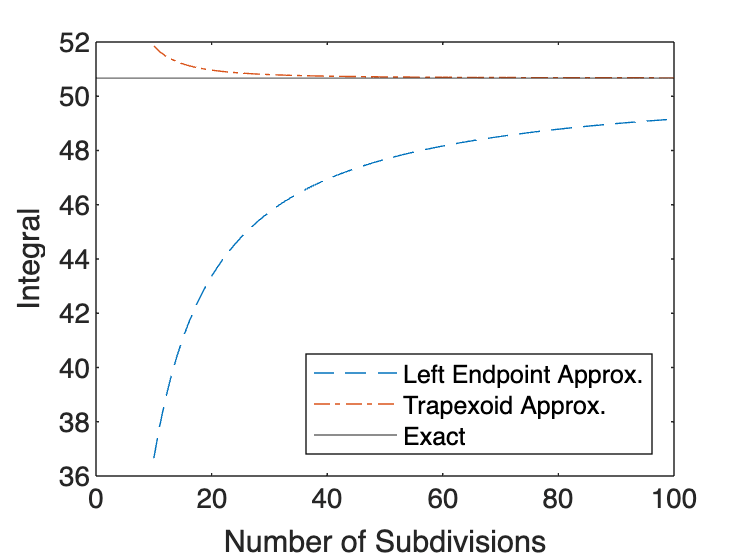


% plot
plot(xs, fL, "--")
hold on
plot(xs, fT, "-.")
yline(SOL)
hold off
legend("Left Endpoint Approx.", "Trapexoid Approx.", "Exact", "Location", "southeast")
xlabel("Number of Subdivisions")
ylabel("Integral")


% error thing
eT = abs(fT-SOL)./SOL

eT =     0.0234
    0.0193
    0.0162
    0.0138
    0.0119
    0.0104
    0.0091
    0.0081
    0.0072
    0.0065


nmin_all = fT(eT < 0.01)

nmin_all =    51.1299
   51.0770
   51.0327
   50.9952
   50.9632
   50.9356
   50.9118
   50.8909
   50.8726
   50.8565


nmin = 17

nmin = 17

fT(7)

ans = 51.1299

nminL = abs(fL(7)-SOL)/SOL

nminL = 0.1784


% second plot
xs = 0:0.01:2

xs =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


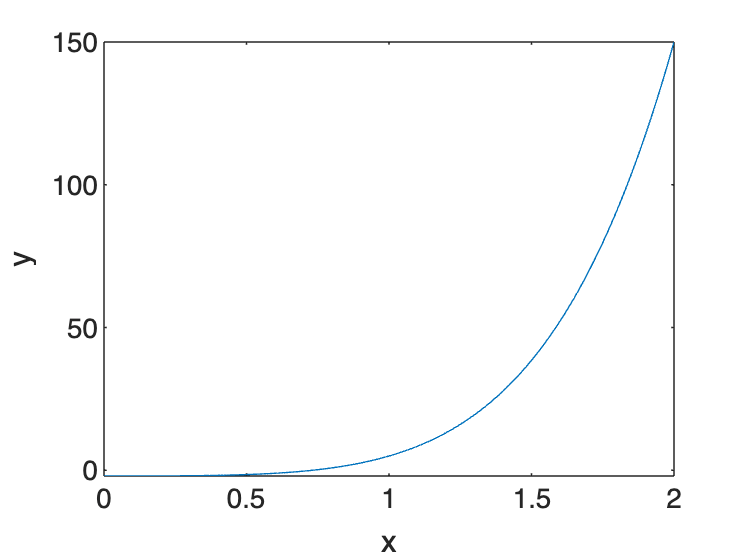

plot(xs, 4 .* xs.^5 + 3 .* xs.^3 - 2)
xlabel("x")
ylabel("y")

**Test 3**